# **Distributed-parameter transducer model**

# **for the stepped amplitude transformer**

**2023-01-03 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

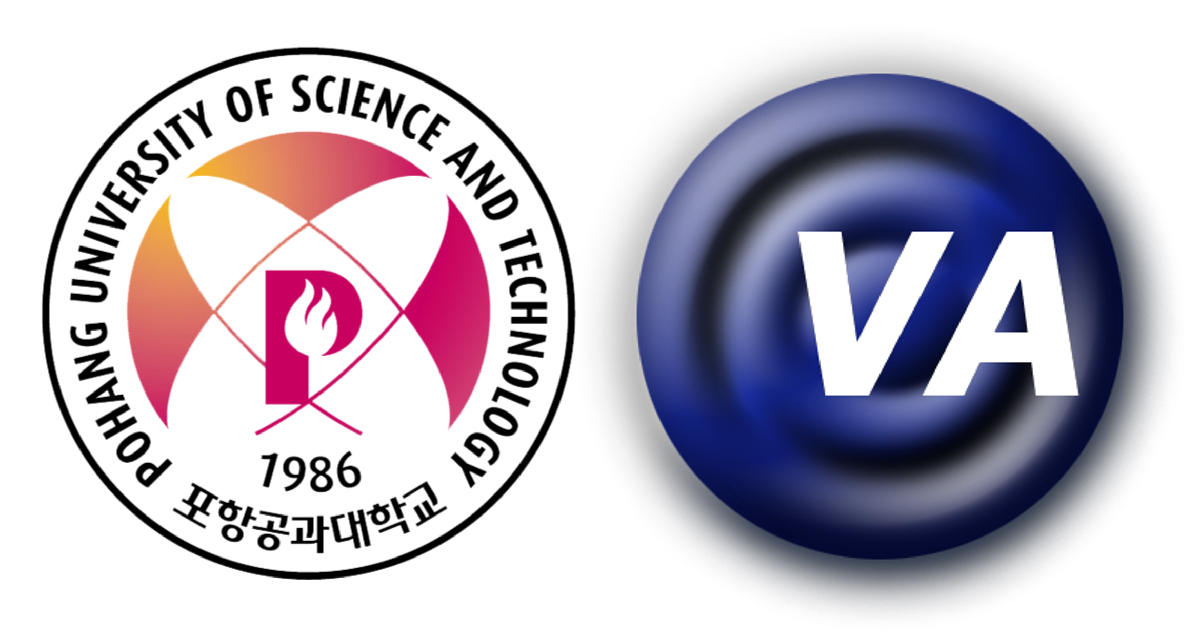

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

The results are saved in **'/results/231212 - Distributed_parameter_transducer_model_DET_231123_r4'.**

clc
clear
close all

% Define the simulation frequency
% f = 75e3;   % 75 [kHz]
syms f

% Load the material properties
mat = import_material('materials_OBS_loss_D.txt');

% Load the plate's impedance
% [~,Z_p_wo_steps] = import_impedance('D -230725 - Stepped-plate impedance w.o. steps.txt');
[Plate.freq,Plate.zSteps] = import_impedance('D -230725 - Stepped-plate impedance w. steps.txt');

Freq.plate0 = 75960;

% Define the structure
n_start = 1;    % Start index of node;
n_end   = 5;    % End index of node;
if n_start > n_end
    disp("Error: the end index of node must be greater than start index!");
    return
end
e_no    = n_end - n_start;
n_no    = e_no+1;
S = sprintf("The number of elements:    %d\n" + ...
    "The number of nodes:       %d",e_no,n_no);
disp(S);

The number of elements:    4
The number of nodes:       5


e_piezo = 2;  % Index of piezoelectric bar

% Initialize the symbols for material properties and design parameters of elements

% Mechanical
rho = sym('rho_%d', [1 n_end]); % Density
E   = sym('E_%d',   [1 n_end]); % Young's modulus
nu  = sym('nu_%d',  [1 n_end]); % Poisson ratio
c   = sym('c_%d',   [1 n_end]); % Longitudinal wave speed
k   = sym('k_%d',   [1 n_end]); % Longitudinal wave number
l   = sym('l_%d',   [1 n_end]); % Length of element
A   = sym('A_%d',   [1 n_end]); % Area of element
Z_p = sym('Z_p');               % Mehcanical impedance of plate

% Electircal
eps_33  = sym('eps_33');        % Dielectric constant, eps_33
N_piezo = sym('N_piezo');       % Number of Piezo

% Mechanical-electrical
d_33    = sym('d_33');          % Piezoelectric charge constant, d_33


The effort and flow variable vectors are $\mathbf{F}=
\left[
\matrix{
F_1\cr
F_2\cr
F_3\cr
\vdots \cr
F_{-2}\cr
F_{-1}\cr
F_0\cr
}
\right]$ and $\mathbf{u}=
\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
\vdots \cr
u_{-2}\cr
u_{-1}\cr
u_0\cr
}
\right]$ where 1 and 0 are the node's start and end indices, and the minus sign is the reversed order from the end index.

% Initialize the symbols for effort and flow variable vectors
F   = sym('F_%d',[1 n_end]).';
u   = sym('u_%d',[1 n_end]).';
V   = sym('V');


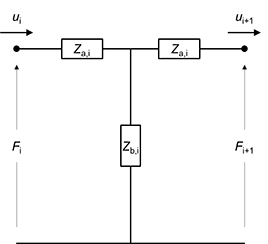

**Figure 1** The symmetric T-network circuit representation of a bar where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

By the KCL,


$$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}\cr
-F_{i+1}\cr
}
\right]$$


% Calculating the bar's impedance for symmetric T-network
Z_b = sym('Z_b_%d',[1 n_end]);  % Z_b
Z_c = sym('Z_c_%d',[1 n_end]);  % Z_c = Z_a + Z_b
Z_d = sym('Z_d_%d',[1 n_end]);  % Z_d for the boundary conditions of both ends

for i=n_start:n_end
    Z_b(i) = -1j*rho(i)*c(i)*A(i)/(sin(k(i)*l(i)));
    Z_c(i) = -1j*rho(i)*c(i)*A(i)*cot(k(i)*l(i));
end

% rho(1:n_start-1)    = [];
% c(1:n_start-1)      = [];
% k(1:n_start-1)      = [];
% l(1:n_start-1)      = [];
% A(1:n_start-1)      = [];


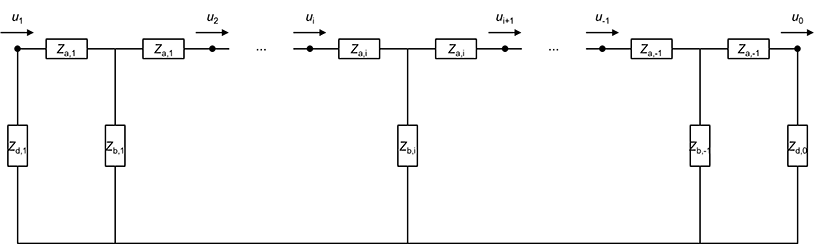

**Figure 2** The symmetric T-network circuit representation of bars mechanically connected in series and its boundary conditions of both ends

When bars are mechanically connected in series and there are the arbitrary impedances, $Z_{\rm{d}}$, at both ends without external force, $\mathbf{F}=\mathbf{Z} \cdot \mathbf{u}=[0]$.

And the impedance matrix is $Z=
\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & \cdots & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} &  \cdots & 0 & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & \cdots & 0 & 0 & 0 \cr
\vdots & \vdots & \vdots & \ddots & \vdots & \vdots & \vdots \cr
0 & 0 & 0 & \cdots & Z_{\rm{c,-3}}+Z_{\rm{c,-2}} & -Z_{\rm{b,-2}} & 0 \cr
0 & 0 & 0 & \cdots & -Z_{\rm{b,-2}} & Z_{\rm{c,-2}}+Z_{\rm{c,-1}} & -Z_{\rm{b,-1}} \cr
0 & 0 & 0 & \cdots & 0 & -Z_{\rm{b,-1}} & Z_{\rm{c,-1}}+Z_{\rm{d,0}} \cr
}
\right]$ where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

% Constructing the impedance matrix
Z = sym('Z_%d_%d',[n_end n_end]);

Z(n_start,n_start)          = Z_c(n_start) + Z_d(n_start);
Z(n_start,n_start+1)        = -Z_b(n_start);
Z(n_start,n_start+2:n_end)  = 0;

for i=n_start+1:n_end-1
    Z(i,n_start:i-2)  = 0;
    Z(i,i-1)    = -Z_b(i-1);
    Z(i,i)      = sum(Z_c(i-1:i));
    Z(i,i+1)    = -Z_b(i);
    Z(i,i+2:n_end)= 0;
end

Z(n_end, n_start:n_end-2) = 0;
Z(n_end, n_end-1)   = -Z_b(n_end-1);
Z(n_end, n_end)     = Z_c(n_end-1) + Z_d(n_end);

Z

$$Z = \begin{array}{l} \left(\begin{array}{ccccc} Z_{d,1}-\sigma_{8} & \sigma_{4} & 0 & 0 & 0\\ \sigma_{4} & -\sigma_{8}-\sigma_{7} & \sigma_{3} & 0 & 0\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & Z_{d,5}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{4}\,c_{4}\,\rho_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{A_{3}\,c_{3}\,\rho_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{A_{1}\,c_{1}\,\rho_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{6}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{7}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{8}=A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} \end{array}$$

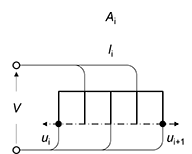

**Figure 3** 4 Piezoelectric bars mechanically connected in series and electrically in parallel

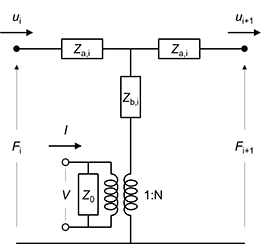

**Figure 4** The symmetric T-network circuit representation of piezoelectric bars mechanically connected in series and electrically in parallel

By KCL,

$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}+NV\cr
-F_{i+1}-NV\cr
}
\right]$where $N=\frac{A_{i} \thinspace d_{33}}{l_{i} \thinspace s_{33}^{E}}$

N = N_piezo*A(e_piezo)*d_33*E(e_piezo)/l(e_piezo);

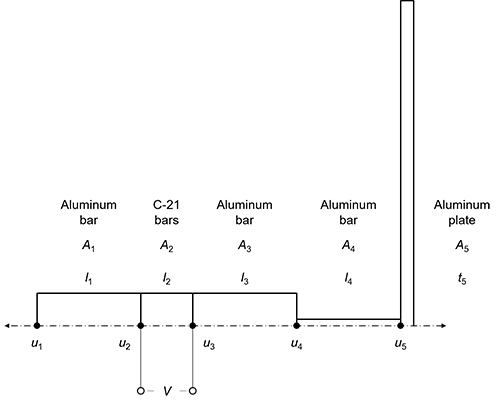

**Figure 5** Typical stepped-plate transducer

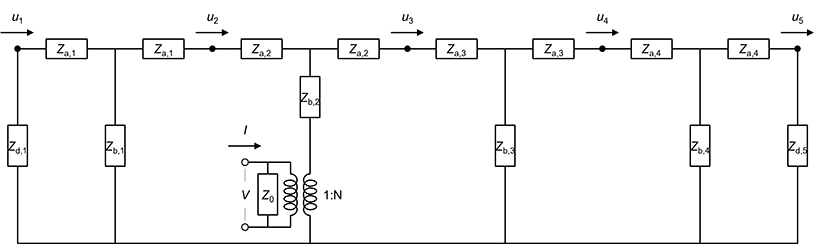

**Figure 6 **The distributed network representation of typical stepped-plate transudcer

By KCL,


$$\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & -Z_{\rm{b,3}} & 0 \cr
0 & 0 & -Z_{\rm{b,3}} & Z_{\rm{c,3}}+Z_{\rm{c,4}} & -Z_{\rm{b,4}} \cr
0 & 0 & 0 & -Z_{\rm{b,4}} & Z_{\rm{c,4}}+Z_{\rm{d,5}} \cr
}
\right]

\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
u_4\cr
u_5\cr
}
\right]

=

\left[
\matrix{
0\cr
NV\cr
-NV\cr
0\cr
0\cr
}
\right]$$


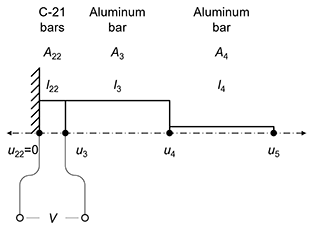

**Figure 7** The aluminum stepped amplitude transformer driven by two piezoelectric bars, C-21, fixed on one end and free on the other end

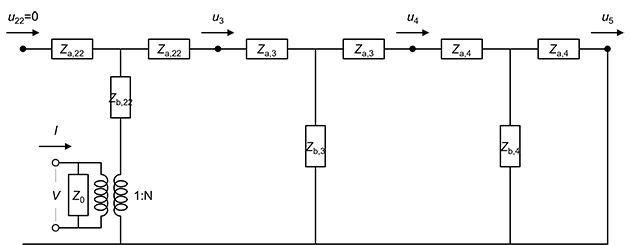

**Figure 8** The distributed network representation of the aluminum stepped amplitude transformer driven by piezoelectric bars

% For the stepped horn

% Applying the volume conditions as material properties

% Define the bounrady conditions of both ends
Z = subs(Z, [Z_d(n_start) Z_d(n_end)], [0 Z_p]);
Z(1:n_start-1,:)    = [];
Z(:,1:n_start-1)    = [];
Z

$$Z = \begin{array}{l} \left(\begin{array}{ccccc} -\sigma_{8} & \sigma_{4} & 0 & 0 & 0\\ \sigma_{4} & -\sigma_{8}-\sigma_{7} & \sigma_{3} & 0 & 0\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & Z_{p}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{4}\,c_{4}\,\rho_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{A_{3}\,c_{3}\,\rho_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{A_{1}\,c_{1}\,\rho_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{6}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{7}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{8}=A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} \end{array}$$

detZ = det(Z)

Define the boundary conditions

- Velocity at node 22, $u_{22}=0$

% u = subs(u, u(n_start), 0);
u(1:n_start-1)  = [];
u

$$u = \left(\begin{array}{c} u_{1}\\ u_{2}\\ u_{3}\\ u_{4}\\ u_{5} \end{array}\right)$$

Define the force conditions

- Force at node 22, $F_{22}=NV$

- Force at node 3, $F_{3}=-NV$

F = subs(F, F(1:e_piezo-1), zeros(e_piezo-1,1));
F = subs(F, F(e_piezo), N*V);
F = subs(F, F(e_piezo+1), - N*V);
F = subs(F, F(e_piezo+2:end), zeros(n_end - e_piezo - 1,1));
F(1:n_start-1)  = [];
F

$$F = \left(\begin{array}{c} 0\\ \frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}}\\ -\frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}}\\ 0\\ 0 \end{array}\right)$$

Solve $\mathbf{Z}\cdot \mathbf{u}=\mathbf{F}$

eqn = Z*u == F

$$eqn = \begin{array}{l} \left(\begin{array}{c} -A_{1}\,c_{1}\,\rho_{1}\,u_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i}+\frac{A_{1}\,c_{1}\,\rho_{1}\,u_{2}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}=0\\ -u_{2}\,\left(A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i}+\sigma_{3}\right)+\frac{A_{1}\,c_{1}\,\rho_{1}\,u_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}+\frac{A_{2}\,c_{2}\,\rho_{2}\,u_{3}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}=\sigma_{4}\\ -u_{3}\,\left(\sigma_{3}+\sigma_{2}\right)+\frac{A_{2}\,c_{2}\,\rho_{2}\,u_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}+\frac{A_{3}\,c_{3}\,\rho_{3}\,u_{4}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}=-\sigma_{4}\\ -u_{4}\,\left(\sigma_{2}+\sigma_{1}\right)+\frac{A_{3}\,c_{3}\,\rho_{3}\,u_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{5}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0\\ u_{5}\,\left(Z_{p}-\sigma_{1}\right)+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{2}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{3}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{4}=\frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}} \end{array}$$

% for i=2:n_no
%     eqn = Z*u == F;
%     u(i) = solve(eqn(i-1),u(i));
% end
% for i=1:n_no
%     eqn = Z*u == F;
%     u(i) = solve(eqn(i),u(i));
% end
% u = Z(2:4,2:4)\F(2:4)
u = Z\F

u1 = u(1);
u2 = u(2);
u3 = u(3);

u5 = u(5);


% createfigure_fr(freq, abs(u_num_w)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s]","linear","log")
% toc

Z1 = mat.rho('C-21')*mat.v3('C-21')*pi*7e-3^2;
Z2 = mat.rho('Stainless Steel')*mat.v3('Stainless Steel')*pi*7e-3^2;
k1 = 2*pi*Freq.plate0/mat.v3('C-21');
k2 = 2*pi*Freq.plate0/mat.v3('Stainless Steel');

l1 = abs(atan(Z1/Z2/tan(k1*2e-3))/k2);

detZ = subs(detZ, A(3), A(2));
detZ = subs(detZ, c(4), c(3));
detZ = subs(detZ, k(4), k(3));
detZ = subs(detZ, rho(4), rho(3));

Substituting the numerical geometric dimensions and material properties into the symbols,

% detZ = subs(detZ, [A(1) A(2) A(4)],       [pi*7e-3^2  pi*7e-3^2   pi*0.75e-3^2]);
detZ = subs(detZ, [A(1) A(2)],       [pi*7e-3^2  pi*7e-3^2]);
% detZ = subs(detZ, [A(2) A(4)],        [pi*7e-3^2  pi*1.5e-3^2]);
detZ = subs(detZ, [l(1) l(2)],  [l1  4e-3]);

detZ = subs(detZ, [E(1) E(2) E(3)],       [mat.Y33('Stainless Steel') mat.Y33('C-21')        mat.Y33('Aluminum')]);
detZ = subs(detZ, [c(1) c(2) c(3)],        [mat.v3('Stainless Steel') mat.v3('C-21')         mat.v3('Aluminum')]);
detZ = subs(detZ, [k(1) k(2) k(3)],        [2*pi*f/mat.v3('Stainless Steel') 2*pi*f/mat.v3('C-21')  2*pi*f/mat.v3('Aluminum')]);
detZ = subs(detZ, [rho(1) rho(2) rho(3)],    [mat.rho('Stainless Steel')   mat.rho('C-21')        mat.rho('Aluminum')]);
detZ = subs(detZ, d_33,               mat.d33('C-21'));
detZ = subs(detZ, N_piezo,            4);

detZ = subs(detZ, V, 10);
% detZ

u5 = subs(u5, A(3), A(2));
u5 = subs(u5, c(4), c(3));
u5 = subs(u5, k(4), k(3));
u5 = subs(u5, rho(4), rho(3));
% Substituting the numerical geometric dimensions and material properties into the symbols,
% u5 = subs(u5, [A(1) A(2) A(4)],       [pi*7e-3^2  pi*7e-3^2   pi*0.75e-3^2]);
u5 = subs(u5, [A(1) A(2)],       [pi*7e-3^2  pi*7e-3^2]);
u5 = subs(u5, [l(1) l(2)],  [l1  4e-3]);

u5 = subs(u5, [E(1) E(2) E(3)],       [mat.Y33('Stainless Steel') mat.Y33('C-21')        mat.Y33('Aluminum')]);
u5 = subs(u5, [c(1) c(2) c(3)],        [mat.v3('Stainless Steel') mat.v3('C-21')         mat.v3('Aluminum')]);
u5 = subs(u5, [k(1) k(2) k(3)],        [2*pi*f/mat.v3('Stainless Steel') 2*pi*f/mat.v3('C-21')  2*pi*f/mat.v3('Aluminum')]);
u5 = subs(u5, [rho(1) rho(2) rho(3)],    [mat.rho('Stainless Steel')   mat.rho('C-21')        mat.rho('Aluminum')]);
u5 = subs(u5, d_33,               mat.d33('C-21'));
u5 = subs(u5, N_piezo,            4);

u5 = subs(u5, V, 10);
% u5

% Symbolic function and function handle of DetZ
symfunDetZ = symfun(detZ,[f,l(3),l(4),A(4),Z_p]);
hfunDetZ = matlabFunction(symfunDetZ);

% Symbolic function and function handle of U5
symfunU5 = symfun(u5,[f,l(3),l(4),A(4),Z_p]);
hfunU5 = matlabFunction(symfunU5);

% Longitudinal Wavelength of Aluminum, \lambda at the plate's 9th resonance
lambda = abs(mat.v3('Aluminum'))/Freq.plate0;

% Angular wavelength for Part 3, k_3*l_3
L3rad.pts   = 80;
L3rad.start = 1*pi; % numeric slide in linear wavelength
L3rad.end   = 2*pi; % e.g.) 0.5 for a quarter wavelength, 1.5 for three quarters wavelength
L3rad.start = L3rad.start + L3rad.end/L3rad.pts;
L3rad.end   = L3rad.end - pi/L3rad.pts;
l3rad       = linspace(L3rad.start,L3rad.end,L3rad.pts);

% Angular wavelength for Part 4
L4rad.pts   = 40;
L4rad.start = 0*pi; % numeric slide in linear wavelength
L4rad.end   = 1*pi; % e.g.) 0.5 for a quarter wavelength, 1.5 for three quarters wavelength
L4rad.start = L4rad.start + L4rad.end/L4rad.pts;
L4rad.end   = L4rad.end - pi/L4rad.pts;
l4rad       = linspace(L4rad.start,L4rad.end,L4rad.pts);

% Frequency
Freq.start  = 73000;
Freq.end    = 79000;
Freq.inc    = 10;
freq        = Freq.start:Freq.inc:Freq.end;

% Radius for Part 4
% R4.pts      = 9;
% R4.start    = 0.5e-3;
% R4.end      = 1.5e-3;
% r4          = sqrt(linspace(R4.start^2,R4.end^2,R4.pts));
r4          = [0.5e-3 0.625e-3 0.75e-3 0.875e-3 1e-3];
a4          = pi*r4.^2;

% Query the points in l3 for slice, contour, and other plots
% Set the values below considering L3rad.start
L3rad.qStart = 0.1; % numeric slide in linear wavelength
L3rad.qEnd   = 0.9; % e.g.) 0.5 for a quarter wavelength, 1.5 for three quarters wavelength
L3rad.qPts = (L3rad.qStart*L3rad.pts:L3rad.qEnd*L3rad.pts);

% Computational domain
[l3rad, l4rad, freq, a4] = ndgrid(l3rad, l4rad, freq, a4);
    % cot(k_3*l_3)
l3cot       = cot(l3rad);
    % Linear wavelength for Part 3, l_3
l3          = l3rad*lambda/2/pi;
    % cot(k_4*l_4)
l4cot       = cot(l4rad);
    % Linear wavelength for Part 4, l_4
l4          = l4rad*lambda/2/pi;
    % Size of ~
nl3     = size(l3cot,1);
nl4     = size(l4cot,2);
nfreq   = size(freq,3);
nr4     = size(a4,4);

% Main calculation
numericDetZ = hfunDetZ(freq,l3,l4,a4,interp1(Plate.freq, Plate.zSteps,freq));
imagDetZ = imag(numericDetZ);
numericU5   = hfunU5(freq,l3,l4,a4,interp1(Plate.freq, Plate.zSteps,freq));

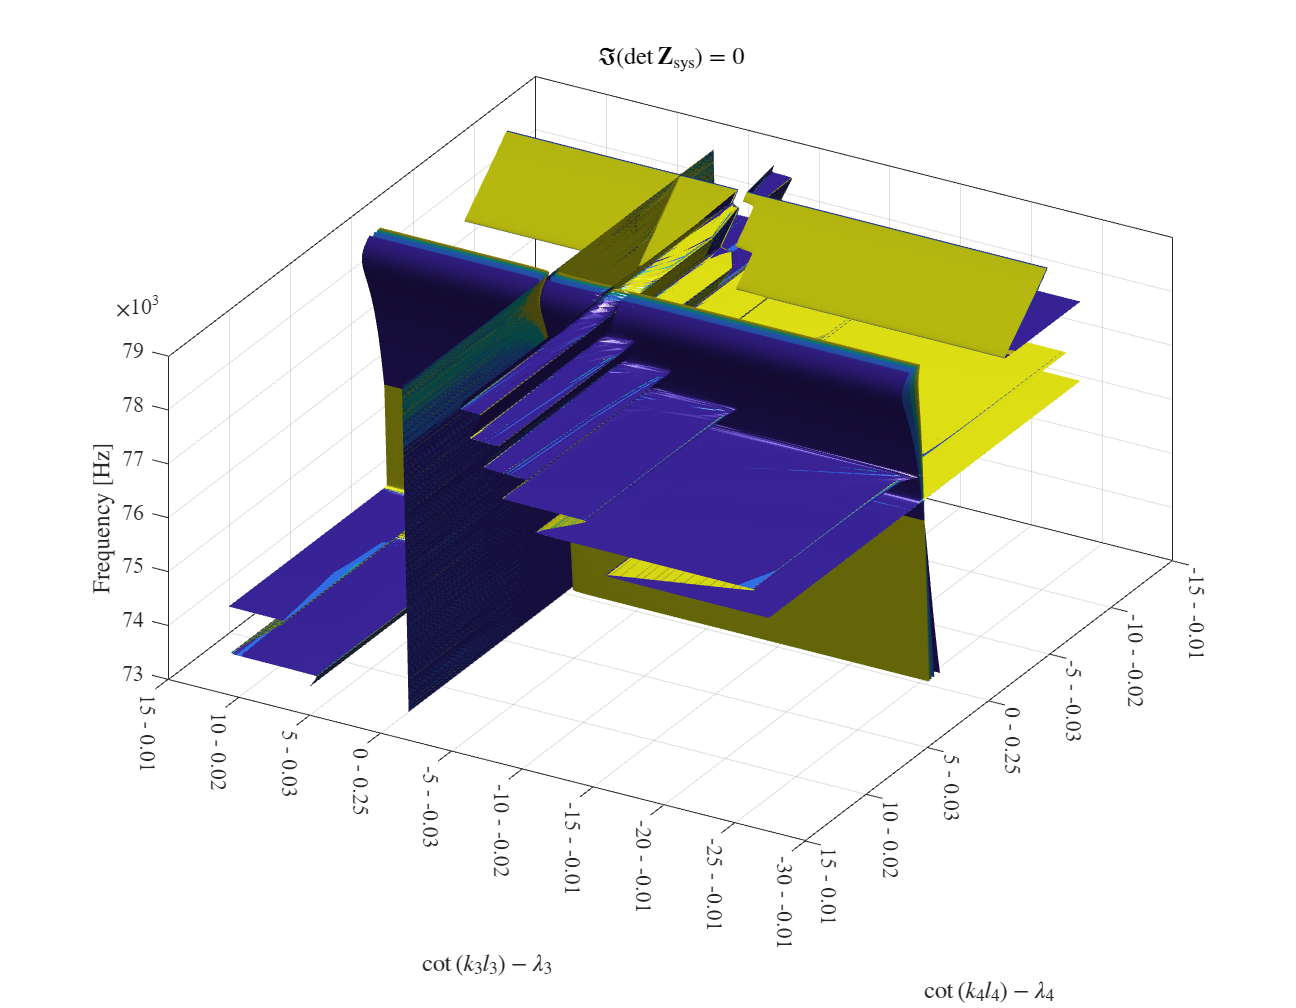

% Create figure
figureImagDetZ0Cot = figure('Name','Figure','Color',[1 1 1],'Units','inches','Position',[1 1 1+8 1+6]);

% Create axes
axesImagDetZ0Cot = axes('Parent',figureImagDetZ0Cot);

cbImagDetZ0Cot = parula(nr4);

hold(axesImagDetZ0Cot, 'on');

for iA4 = 1:nr4
    sImagDetZ0Cot = isosurface(pagetranspose(squeeze(l3cot(:,:,:,iA4))), ...
        pagetranspose(squeeze(l4cot(:,:,:,iA4))), ...
        pagetranspose(squeeze(freq(:,:,:,iA4))), ...
        pagetranspose(squeeze(imagDetZ(:,:,:,iA4))), 0);
    pImagDetZ0Cot = patch(sImagDetZ0Cot);
    isonormals(pagetranspose(squeeze(l3cot(:,:,:,iA4))), ...
        pagetranspose(squeeze(l4cot(:,:,:,iA4))), ...
        pagetranspose(squeeze(freq(:,:,:,iA4))), ...
        pagetranspose(squeeze(imagDetZ(:,:,:,iA4))), ...
        pagetranspose(pImagDetZ0Cot))
    pImagDetZ0Cot.FaceColor = cbImagDetZ0Cot(iA4,:);
    pImagDetZ0Cot.EdgeColor = 'none';
end

% Create light
light('Position',[-2*max(abs(l3cot(:,1,1))) 6*max(abs(l4cot(1,:,1))) 2*Freq.plate0],...
    'Style','local');

% xlim(axesImagDetZ0Cot,[0 1])
% ylim(axesImagDetZ0Cot,[0 1])

% Create xlabel
xlabel('$\cot{(k_3 l_3)} - \lambda_3$','Interpreter','latex');
% axesImagDetZ0.XAxis.Exponent = 1;
axesImagDetZ0Cot.XTickLabel = strcat(cellstr(axesImagDetZ0Cot.XTickLabel), ...
    cellstr(repmat(" - ",length(axesImagDetZ0Cot.XTick),1)), ...
    compose('%.2f',acot(axesImagDetZ0Cot.XTick')/2/pi));
xtickangle(axesImagDetZ0Cot,-90)

% Create ylabel
ylabel('$\cot{(k_4 l_4)} - \lambda_4$','Interpreter','latex');
% axesImagDetZ0.YAxis.Exponent = 1;
axesImagDetZ0Cot.YTickLabel = strcat(cellstr(axesImagDetZ0Cot.YTickLabel), ...
    cellstr(repmat(" - ",length(axesImagDetZ0Cot.YTick),1)), ...
    compose('%.2f',acot(axesImagDetZ0Cot.YTick')/2/pi));
ytickangle(axesImagDetZ0Cot,-90)

% Create zlabel
zlabel('Frequency [Hz]','Interpreter','latex');
axesImagDetZ0Cot.ZAxis.Exponent = 3;

% Create title
title('$\Im{\left(\det{\bf{Z}_\mathrm{sys}}\right)}=0$','Interpreter','latex');

view(axesImagDetZ0Cot,[-150 45]);
% view(axes1,3);
hold(axesImagDetZ0Cot, 'off');
box(axesImagDetZ0Cot,'on');
grid(axesImagDetZ0Cot,'on');
% Set the remaining axes properties
set(axesImagDetZ0Cot,'FontName','Times New Roman','FontSize',11);

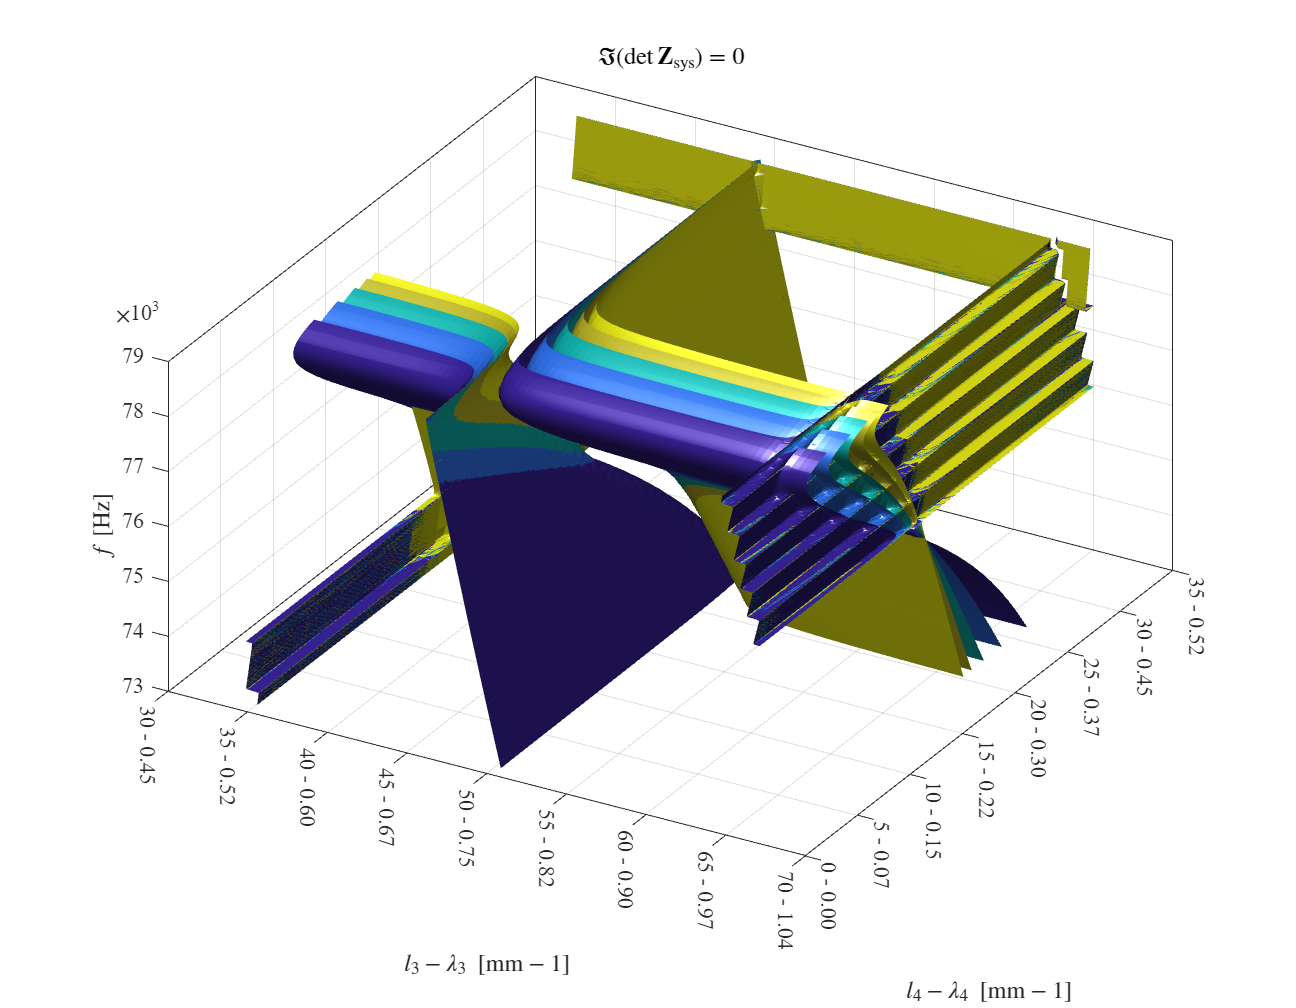

% Create figure
figureImagDetZ0 = figure('Name','Figure','Color',[1 1 1],'Units','inches','Position',[1 1 1+8 1+6]);

% Create axes
axesImagDetZ0 = axes('Parent',figureImagDetZ0);
cbImagDetZ0 = parula(nr4);

hold(axesImagDetZ0, 'on');

for iA4 = 1:nr4
    sImagDetZ0 = isosurface(pagetranspose(squeeze(l3(:,:,:,iA4))), ...
        pagetranspose(squeeze(l4(:,:,:,iA4))), ...
        pagetranspose(squeeze(freq(:,:,:,iA4))), ...
        pagetranspose(squeeze(imagDetZ(:,:,:,iA4))), 0);
    pImagDetZ0 = patch(sImagDetZ0);
    isonormals(pagetranspose(squeeze(l3(:,:,:,iA4))), ...
        pagetranspose(squeeze(l4(:,:,:,iA4))), ...
        pagetranspose(squeeze(freq(:,:,:,iA4))), ...
        pagetranspose(squeeze(imagDetZ(:,:,:,iA4))), ...
        pagetranspose(pImagDetZ0))
    pImagDetZ0.FaceColor = cbImagDetZ0(iA4,:);
    pImagDetZ0.EdgeColor = 'none';
end

% Create light
light('Position',[2*max(abs(l3(:,1,1))) -6*max(abs(l4(1,:,1))) 2*Freq.plate0],...
    'Style','local');

% Create xlabel
xlabel('$l_3 - \lambda_3 \ \left[ \mathrm{mm} - 1 \right]$','Interpreter','latex');
axesImagDetZ0.XAxis.Exponent = -3;
axesImagDetZ0.XTickLabel = strcat(cellstr(axesImagDetZ0.XTickLabel), ...
    cellstr(repmat(" - ",length(axesImagDetZ0.XTick),1)), ...
    compose('%.2f',(axesImagDetZ0.XTick')/lambda));
xtickangle(axesImagDetZ0,-90)

% Create ylabel
ylabel('$l_4 - \lambda_4 \ \left[ \mathrm{mm} - 1 \right]$','Interpreter','latex');
axesImagDetZ0.YAxis.Exponent = -3;
axesImagDetZ0.YTickLabel = strcat(cellstr(axesImagDetZ0.YTickLabel), ...
    cellstr(repmat(" - ",length(axesImagDetZ0.YTick),1)), ...
    compose('%.2f',(axesImagDetZ0.YTick')/lambda));
ytickangle(axesImagDetZ0,-90)

% Create zlabel
zlabel('$f$ [Hz]','Interpreter','latex');
axesImagDetZ0.ZAxis.Exponent = 3;

% Create title
title('$\Im{\left(\det{\bf{Z}_\mathrm{sys}}\right)}=0$','Interpreter','latex');

view(axesImagDetZ0,[30 45]);
% view(axes1,3);
box(axesImagDetZ0,'on');
grid(axesImagDetZ0,'on');
% Set the remaining axes properties
set(axesImagDetZ0,'FontName','Times New Roman','FontSize',11);

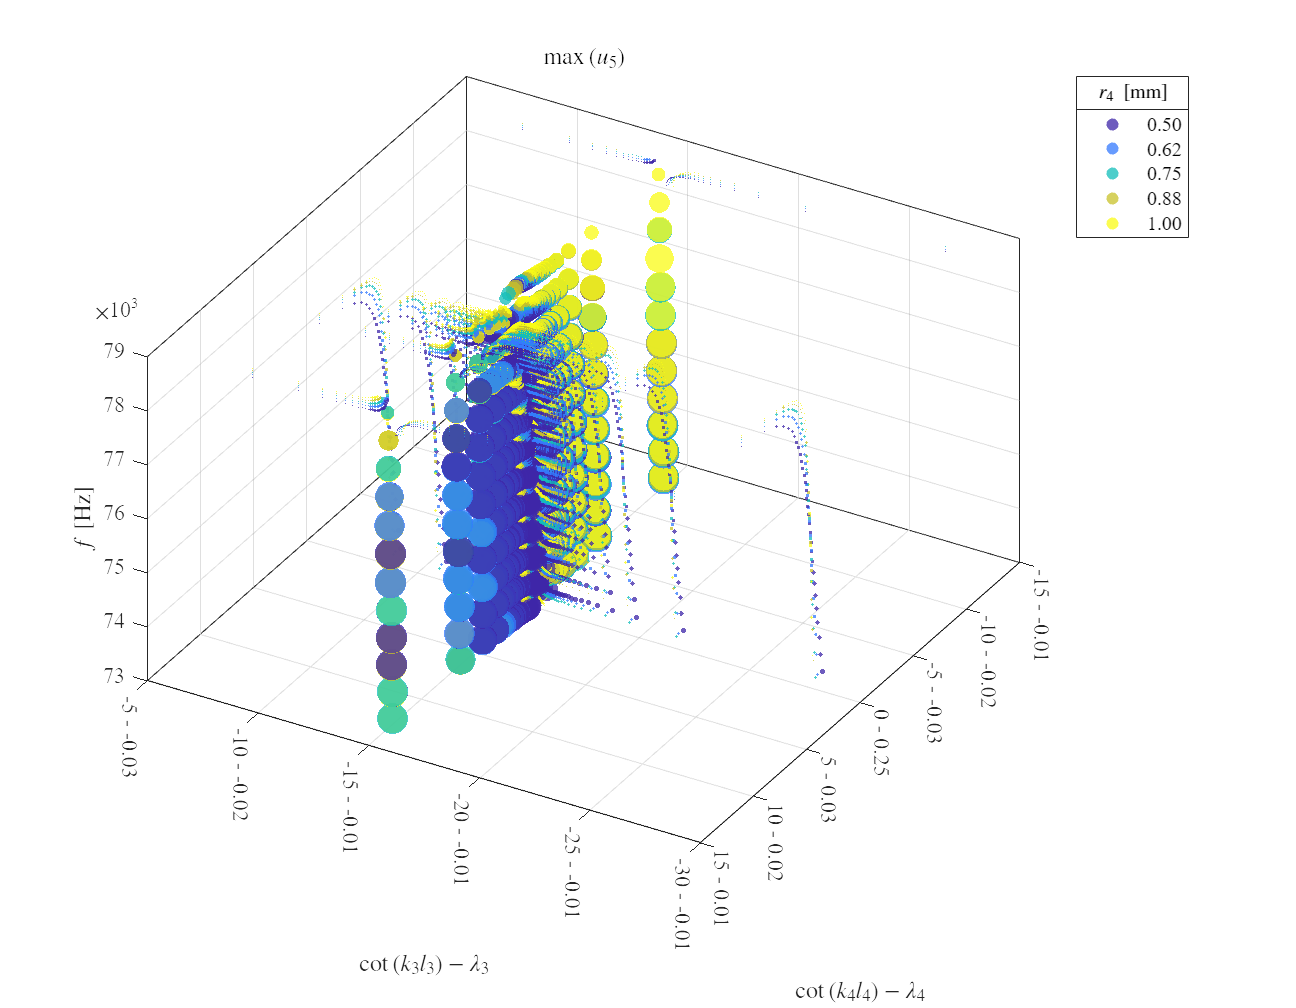

TF = islocalmax(abs(numericU5),3);

% Create figure
figureMaxU5Cot = figure('Name','Figure','Color',[1 1 1],'Units','inches','Position',[1 1 1+8 1+6]);

% Create axes
axesMaxU5Cot = axes('Parent',figureMaxU5Cot);

% cbMaxU5Cot = parula(nr4);
hold(axesMaxU5Cot, 'on');

for iA4 = 1:nr4
    scatter3(l3cot(TF(:,:,:,iA4)), l4cot(TF(:,:,:,iA4)), freq(TF(:,:,:,iA4)),100*abs(numericU5(TF(:,:,:,iA4))),cbImagDetZ0(iA4,:), ...
        'filled','MarkerFaceAlpha',0.75,'DisplayName',num2str(r4(iA4)*1e3,'%1.2f'))
%     scatter3(l3cot(TF(:,:,:,iA4)), l4cot(TF(:,:,:,iA4)), freq(TF(:,:,:,iA4)),5.^abs(numericU5(TF(:,:,:,iA4))),abs(numericU5(TF(:,:,:,iA4))),'filled')
%     colormap(cubehelix([],pi/(nr4-1)*(iA4-1),1,1.5,1,[0.3,0.7],[0.3,0.7]));
end

% % % Comment the script below if it does not represent the detZ
% sImagDetZ0Cot = isosurface(l3cot, l4cot, freq, imagDetZ, 0);
% pImagDetZ0Cot = patch(sImagDetZ0Cot);
% isonormals(l3cot, l4cot, freq, imagDetZ, pImagDetZ0Cot)
% pImagDetZ0Cot.FaceColor = [1 1 1];
% pImagDetZ0Cot.EdgeColor = 'none';
% % % Comment the script above if it does not represent the detZ

view(axesMaxU5Cot,[-150 45]);

% Create light
light('Position',[2*max(abs(l3(:,1,1))) -6*max(abs(l4(1,:,1))) 2*Freq.plate0],...
    'Style','local');

% xlim(axesMaxU5Cot,[0 1])
% ylim(axesMaxU5Cot,[0 1])

% cbMaxU5Cot = colorbar(axesMaxU5Cot);
% cbMaxU5Cot.Label.Interpreter = 'latex';
% cbMaxU5Cot.Label.String = '$\left| u_{5}\right|\ \left[\mathrm{m/s}\right]$';

% Create title
title('$\max{\left(u_5\right)}$','Interpreter','latex');

% view(axes1,3);
hold(axesMaxU5Cot, 'off');
box(axesMaxU5Cot,'on');
grid(axesMaxU5Cot,'on');
% Set the remaining axes properties
set(axesMaxU5Cot,'FontName','Times New Roman','FontSize',11);
% Create xlabel
xlabel('$\cot{(k_3 l_3)} - \lambda_3$','Interpreter','latex');
% axesMaxU5Cot.XAxis.Exponent = 1;
axesMaxU5Cot.XTickLabel = strcat(cellstr(axesMaxU5Cot.XTickLabel), ...
    cellstr(repmat(" - ",length(axesMaxU5Cot.XTick),1)), ...
    compose('%.2f',acot(axesMaxU5Cot.XTick')/2/pi));
xtickangle(axesMaxU5Cot,-90)

% Create ylabel
ylabel('$\cot{(k_4 l_4)} - \lambda_4$','Interpreter','latex');
% axesMaxU5Cot.YAxis.Exponent = 1;
axesMaxU5Cot.YTickLabel = strcat(cellstr(axesMaxU5Cot.YTickLabel), ...
    cellstr(repmat(" - ",length(axesMaxU5Cot.YTick),1)), ...
    compose('%.2f',acot(axesMaxU5Cot.YTick')/2/pi));
ytickangle(axesMaxU5Cot,-90)

% Create zlabel
zlabel('$f$ [Hz]','Interpreter','latex');
axesMaxU5Cot.ZAxis.Exponent = 3;

% Create legend
lgdMaxU5Cot = legend(axesMaxU5Cot,'show');
title(lgdMaxU5Cot,'$r_4 \ \left[ \mathrm{mm} \right]$','Interpreter','latex')

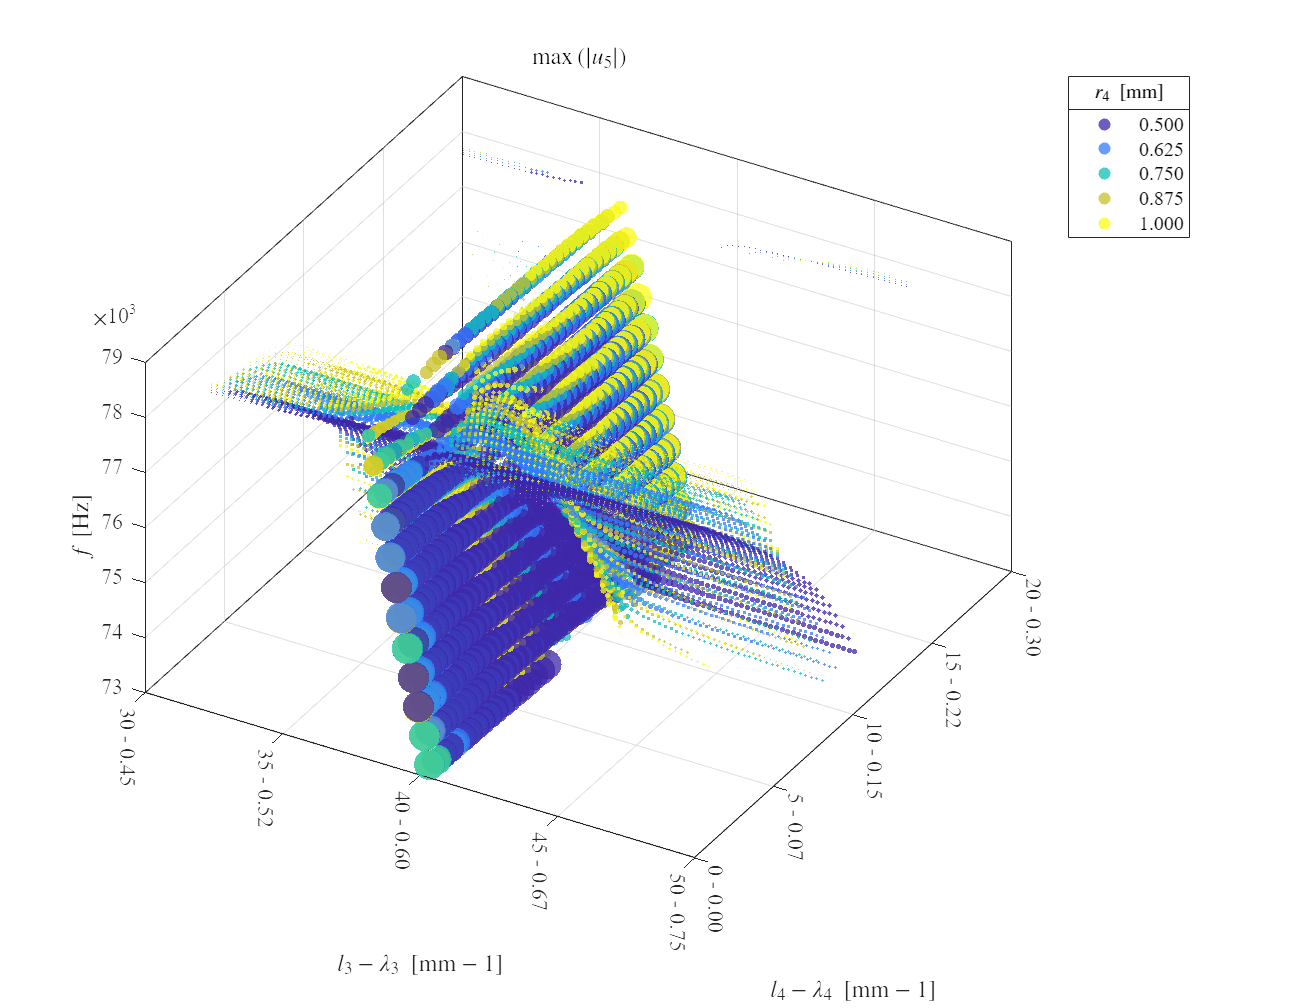

% Create figure
figureMaxU5 = figure('Name','Figure','Color',[1 1 1],'Units','inches','Position',[1 1 1+8 1+6]);

% Create axes
axesMaxU5 = axes('Parent',figureMaxU5);

hold(axesMaxU5, 'on');

for iA4 = 1:nr4
    scatter3(l3(TF(:,:,:,iA4)), l4(TF(:,:,:,iA4)), freq(TF(:,:,:,iA4)),100*abs(numericU5(TF(:,:,:,iA4))),cbImagDetZ0(iA4,:), ...
        'filled','MarkerFaceAlpha',0.75,'DisplayName',num2str(r4(iA4)*1e3,'%1.3f'))
end

% scatter3(l3(TF), l4(TF), freq(TF),5.^abs(numericU5(TF)),abs(numericU5(TF)),'filled')

% % % Comment the script below if it does not represent the detZ
% sImagDetZ0 = isosurface(l3, l4, freq, imagDetZ, 0);
% pImagDetZ0 = patch(sImagDetZ0);
% isonormals(l3, l4, freq, imagDetZ, pImagDetZ0)
% pImagDetZ0.FaceColor = [1 1 1];
% pImagDetZ0.EdgeColor = 'none';
% % % Comment the script above if it does not represent the detZ

% Create light
light('Position',[2*max(abs(l3(:,1,1))) -6*max(abs(l4(1,:,1))) 2*Freq.plate0],...
    'Style','local');

% cbMaxU5 = colorbar(axesMaxU5);
% cbMaxU5.Label.Interpreter = 'latex';
% cbMaxU5.Label.String = '$\left| u_{5}\right| \ \left[\mathrm{m/s}\right]$';

% Create title
title('$\max{\left(\left|u_5\right|\right)}$','Interpreter','latex');

view(axesMaxU5,[30 45]);
% view(axes1,3);
box(axesMaxU5,'on');
grid(axesMaxU5,'on');
% Set the remaining axes properties
set(axesMaxU5,'FontName','Times New Roman','FontSize',11);

% Create xlabel
xlabel('$l_3 - \lambda_3 \ \left[ \mathrm{mm} - 1 \right]$','Interpreter','latex');
axesMaxU5.XAxis.Exponent = -3;
axesMaxU5.XTickLabel = strcat(cellstr(axesMaxU5.XTickLabel), ...
    cellstr(repmat(" - ",length(axesMaxU5.XTick),1)), ...
    compose('%.2f',(axesMaxU5.XTick')/lambda));
xtickangle(axesMaxU5,-90)

% Create ylabel
ylabel('$l_4 - \lambda_4 \ \left[ \mathrm{mm} - 1 \right]$','Interpreter','latex');
axesMaxU5.YAxis.Exponent = -3;
axesMaxU5.YTickLabel = strcat(cellstr(axesMaxU5.YTickLabel), ...
    cellstr(repmat(" - ",length(axesMaxU5.YTick),1)), ...
    compose('%.2f',(axesMaxU5.YTick')/lambda));
ytickangle(axesMaxU5,-90)

% Create zlabel
zlabel('$f$ [Hz]','Interpreter','latex');
axesMaxU5.ZAxis.Exponent = 3;
% Create legend
lgdMaxU5 = legend(axesMaxU5,'show');
title(lgdMaxU5,'$r_4 \ \left[ \mathrm{mm} \right]$','Interpreter','latex')

run = false; % Check if run section
if run == true
    % Create figure
    figureMaxU5Slice = figure('Name','Figure','Color',[1 1 1],'Units','inches','Position',[1 1 1+8 1+6]);
    
    % Create axes
    axesMaxU5Slice = axes('Parent',figureMaxU5Slice);
    
    hMaxU5Slice = slice(l3,l4,freq,(abs(numericU5)),squeeze(l3(1,L3rad.qPts,1)),[],[]);
    % hMaxU5Slice = slice(l3,l4,freq,log10(abs(numericU5)),squeeze(l3(1,L3rad.qPts,1)),[],[]);
    
    % colormap(flipud(hot));
    
    % set(hMaxU5Slice, 'EdgeColor', 'interp');
    set(hMaxU5Slice, 'EdgeColor', 'none');
    % set(hMaxU5Slice, 'FaceAlpha', 0.1);
    
    view(axesMaxU5Slice,[-30 45]);
    
    cbMaxU5Slice = colorbar(axesMaxU5Slice);
    cbMaxU5Slice.Label.Interpreter = 'latex';
    cbMaxU5Slice.Label.String = '$\left| u_{5}\right| \left[\mathrm{m/s}\right]$';
    
    % Create title
    title('$\max{\left(\left|u_5\right|\right)}$','Interpreter','latex');
    
    box(axesMaxU5Slice,'on');
    grid(axesMaxU5Slice,'on');
    % Set the remaining axes properties
    set(axesMaxU5Slice,'FontName','Times New Roman','FontSize',11);
    
    % Create xlabel
    xlabel('$l_3 - \lambda_3 \ \left[ \mathrm{mm} - 1 \right]$','Interpreter','latex');
    axesMaxU5Slice.XAxis.Exponent = -3;
    axesMaxU5Slice.XTickLabel = strcat(cellstr(axesMaxU5Slice.XTickLabel), ...
        cellstr(repmat(" - ",length(axesMaxU5Slice.XTick),1)), ...
        compose('%.2f',(axesMaxU5Slice.XTick')/lambda));
    xtickangle(axesMaxU5Slice,-90)
    
    % Create ylabel
    ylabel('$l_4 - \lambda_4 \ \left[ \mathrm{mm} - 1 \right]$','Interpreter','latex');
    axesMaxU5Slice.YAxis.Exponent = -3;
    axesMaxU5Slice.YTickLabel = strcat(cellstr(axesMaxU5Slice.YTickLabel), ...
        cellstr(repmat(" - ",length(axesMaxU5Slice.YTick),1)), ...
        compose('%.2f',(axesMaxU5Slice.YTick')/lambda));
    ytickangle(axesMaxU5Slice,-90)
    
    % Create zlabel
    zlabel('$f$ [Hz]','Interpreter','latex');
    axesMaxU5Slice.ZAxis.Exponent = 3;
end

run = false; % Check if run section
if run == true
    for i = L3rad.qPts
    
        % Create figure
        figureMaxU5Contour = figure('Name','Figure','Color',[1 1 1],'Units','inches','Position',[1 1 1+8 1+6]);
    
        % Create axes
        axesMaxU5Contour = axes('Parent',figureMaxU5Contour);
    
        % contourf(squeeze(l4(:,L3rad.qPts,:)), ...
        %     squeeze(freq(:,L3rad.qPts,:)), ...
        %     (abs(squeeze(numericU5(:,L3rad.qPts,:)))),'LineStyle','none');
        contourf(squeeze(l4(:,i,:)), ...
            squeeze(freq(:,i,:)), ...
            log10(abs(squeeze(numericU5(:,i,:)))),'LineStyle','none');
        
        cbMaxU5Contour = colorbar(axesMaxU5Contour);
        cbMaxU5Contour.Label.Interpreter = 'latex';
        cbMaxU5Contour.Label.String = '$\log_{10} \left( \left| u_{5}\right|\ \right) \left[\mathrm{m/s}\right]$';

        % Create xlabel
        xlabel({'$l_4 \ \left[ \mathrm{mm} \right]$','$\lambda_4 \ \left[ 1 \right]$'},'Interpreter','latex');
        axesMaxU5Contour.XAxis.Exponent = -3;
        axesMaxU5Contour.XTickLabel = strcat(cellstr(axesMaxU5Contour.XTickLabel), ...
            cellstr(repmat("\newline",length(axesMaxU5Contour.XTick),1)), ...
            compose('%.2f',(axesMaxU5Contour.XTick')/lambda));
        xtickangle(axesMaxU5Contour,0)
    
        % Create ylabel
        ylabel('$f$ [Hz]','Interpreter','latex');
        axesMaxU5Contour.YAxis.Exponent = 3;
    
        % Create title
        % title(['$\max{\left(u_5\right)},\ l_3 = $' num2str(l3(1,L3rad.qPts,1)*1e3,'%.2f') '$\ \left[ \mathrm{mm} \right]$'],'Interpreter','latex');
        title(['$\log_{10}{\left(\max{\left(\left|u_5\right|\right)}\right)},\ l_3 = $' ...
            num2str(l3(1,i,1)*1e3,'%.2f') '$\ \left[ \mathrm{mm} \right],\ \lambda_3 = $' ...
            num2str(l3(1,i,1)/lambda,'%.3f') '$\ \left[ 1 \right]$'],'Interpreter','latex');
    
        box(axesMaxU5Contour,'on');
        grid(axesMaxU5Contour,'off');
        colorbar(axesMaxU5Contour);
        % Set the remaining axes properties
        set(axesMaxU5Contour,'FontName','Times New Roman','FontSize',11);
    end
end

% [TF1, P1] = islocalmax(abs(numericU5));
c = parula(256);
Freq.min = 1e2;

iA4 = 1;
run = false; % Check if run section
if run == true
    for i = L3rad.qPts
        % Create figure
        figureU5 = figure('Name','Figure','Color',[1 1 1],'Units','inches','Position',[1 1 1+12 1+6]);
    
        % Create axes
        axesU5 = axes('Parent',figureU5);
    
        freqTemp = squeeze(freq(i,:,:,iA4));
        u5Temp = abs(squeeze(numericU5(i,:,:,iA4)));
    
        hold(axesU5, 'on');
    
        % for j = 1:nl4
        for j = nl4:-1:1
            [TF2, P2] = islocalmax(u5Temp(j,:));
    
            if(length(freqTemp(j,TF2)) == 2)
                % plot(freqTemp(j,TF2),u5Temp(j,TF2))
                freqDoubleMax = freqTemp(j,TF2);
                u5DoubleMax = u5Temp(j,TF2);
                freqDist = pdist(freqDoubleMax');
                % pdist(u5DoubleMax')
                % plot(freqTemp(j,TF2),u5Temp(j,TF2),'Color',c(floor((1-(freqDist-1e2)/8e3)*256),:),'LineWidth',10^(1-(freqDist-1e2)/8e3),'DisplayName',num2str(freqDist))
                % semilogy(freqTemp(j,:),u5Temp(j,:),'Color',c(floor((1-(freqDist-1e2)/8e3)*256),:),'LineWidth',10^(1-(freqDist-1e2)/8e3),'HandleVisibility','off')
                plot(freqTemp(j,TF2),u5Temp(j,TF2),'Color',c(floor((1-(freqDist-Freq.min)/(Freq.end-Freq.start))*256),:), ...
                    'LineWidth',1,'DisplayName',[num2str(freqDist) ', ' num2str(1e3*squeeze(l4(i,j,1)),'%05.2f') ', ' num2str(squeeze(l4(i,j,1)/lambda),'%05.3f')])
                semilogy(freqTemp(j,:),u5Temp(j,:),'Color',c(floor((1-(freqDist-Freq.min)/(Freq.end-Freq.start))*256),:), ...
                    'LineWidth',1,'HandleVisibility','off')
            end
        end
    
        ylim(axesU5, [1e-1 1e1])
    
        % Create xlabel
        xlabel('$f$ [Hz]','Interpreter','latex');
        axesU5.XAxis.Exponent = 3;
    
        % Create ylabel
        ylabel('$\left|u_5\right| \ \left[ \mathrm{m/s} \right]$','Interpreter','latex');
    
        % Create title
        title(['$r_4 = $' num2str(r4(iA4)*1e3,'%.2f') ...
            '$\ \left[ \mathrm{mm} \right],\ l_3 = $' num2str(l3(i,1,1,iA4)*1e3,'%.2f') ...
            '$\ \left[ \mathrm{mm} \right],\ \lambda_3 = $' num2str(l3(i,1,1,iA4)/lambda,'%.3f') ...
            '$\ \left[ 1 \right]$'],'Interpreter','latex');
    
        box(axesU5,'on');
        hold(axesU5,'off');
    
        % Set the remaining axes properties
        set(axesU5,'XGrid','on','YGrid','on','YMinorTick','on','YScale','log','FontName','Times New Roman','FontSize',11);
    
        % Create legend
        legendU5 = legend(axesU5,'show');
        set(legendU5,'NumColumns',2,'Location','eastoutside','LimitMaxLegendEntries', false);
        title(legendU5,'$f_2-f_1 \ \left[ \mathrm{Hz} \right],\ l_4 \ \left[ \mathrm{mm} \right],\ \lambda_4 \ \left[ 1 \right]$','Interpreter','latex');
    
        % set(figureU5,'Visible','on')
    end
end

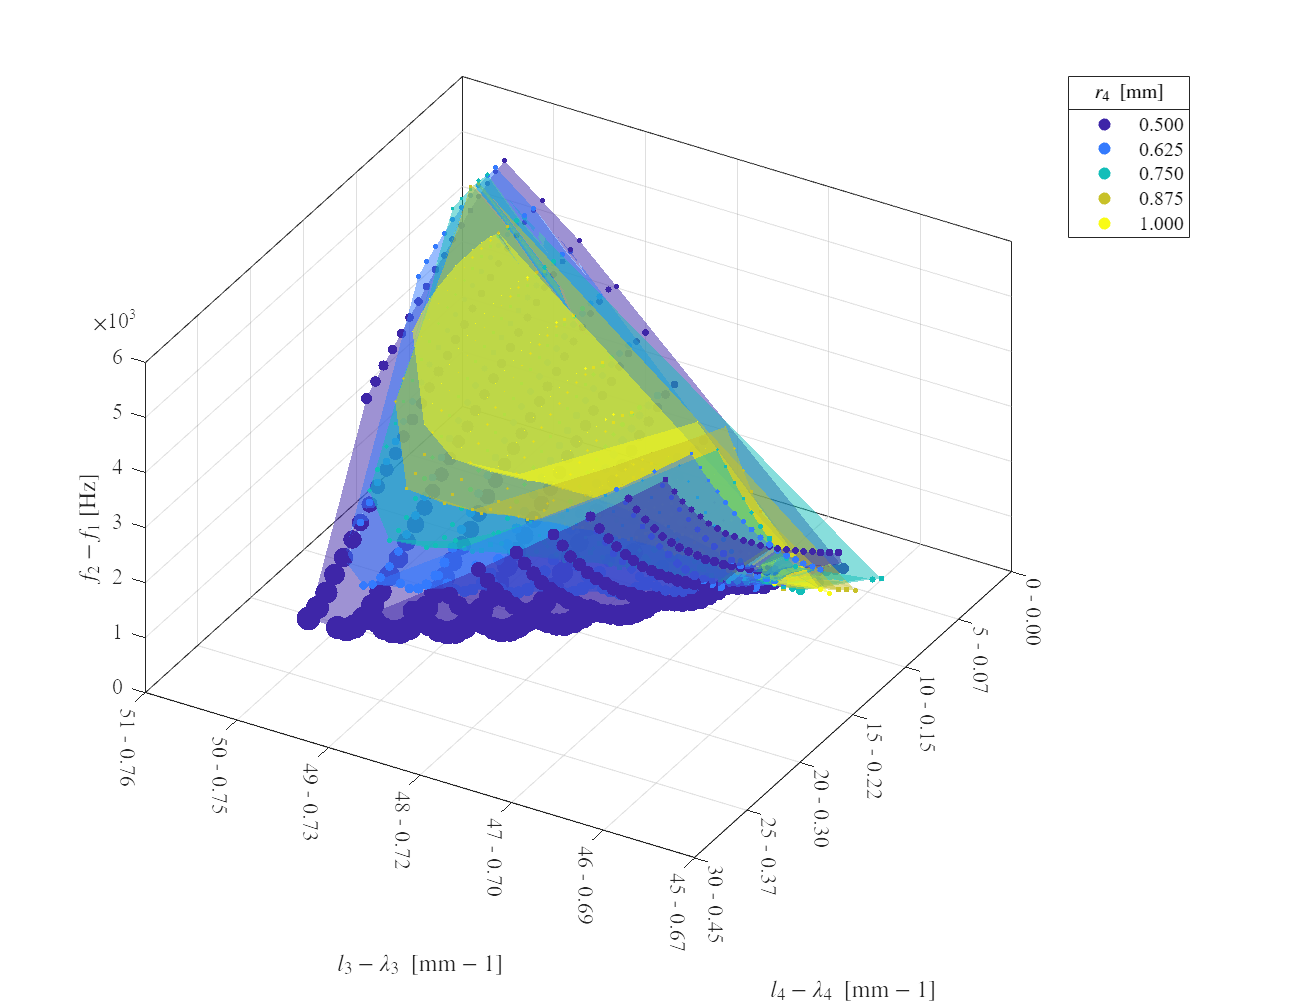

% Create figure
figureU5DoubleMax = figure('Name','Figure','Color',[1 1 1],'Units','inches','Position',[1 1 1+8 1+6]);

% Create axes
axesU5DoubleMax = axes('Parent',figureU5DoubleMax);

hold(axesU5DoubleMax, 'on');

for iA4 = 1:nr4
    clear l3l4fu5DoubleMax
    clear tri

    l3l4fu5Max = [l3(TF(:,:,:,iA4)), l4(TF(:,:,:,iA4)), freq(TF(:,:,:,iA4)), numericU5(TF(:,:,:,iA4))];
    j = 1;
    for i=1:length(l3l4fu5Max)
        identicalIndices = find(ismember(l3l4fu5Max(:,1:2), l3l4fu5Max(i,1:2), 'rows'));
        if length(identicalIndices) == 2
            l3l4fu5DoubleMax(j,:) = [l3l4fu5Max(i,1:2) pdist(l3l4fu5Max(identicalIndices,3)) abs(l3l4fu5Max(identicalIndices(1),4))*abs(l3l4fu5Max(identicalIndices(2),4))];
        end
        j=j+1;
    end

    if exist('l3l4fu5DoubleMax','var')
    else
        break
    end

    l3l4fu5DoubleMax = [nonzeros(l3l4fu5DoubleMax(:,1)),nonzeros(l3l4fu5DoubleMax(:,2)),nonzeros(l3l4fu5DoubleMax(:,3)),nonzeros(l3l4fu5DoubleMax(:,4))];
    l3l4fu5DoubleMax = unique(l3l4fu5DoubleMax,'rows');
    
    % scatter3(l3l4fu5DoubleMax(:,1),l3l4fu5DoubleMax(:,2),l3l4fu5DoubleMax(:,3),5.^nonzeros(l3l4fu5DoubleMax(:,4)),nonzeros(l3l4fu5DoubleMax(:,4)),'filled')
    scatter3(l3l4fu5DoubleMax(:,1),l3l4fu5DoubleMax(:,2),l3l4fu5DoubleMax(:,3),100*nonzeros(l3l4fu5DoubleMax(:,4)),cbImagDetZ0(iA4,:),'filled','DisplayName',num2str(r4(iA4)*1e3,'%1.3f'))

    if size(l3l4fu5DoubleMax,1) > 2
        tri = delaunay(l3l4fu5DoubleMax(:,1),l3l4fu5DoubleMax(:,2));
        trisurf(tri,l3l4fu5DoubleMax(:,1),l3l4fu5DoubleMax(:,2),l3l4fu5DoubleMax(:,3),'FaceColor',cbImagDetZ0(iA4,:),'FaceAlpha',0.5,'EdgeColor','none','HandleVisibility','off');
    end
end

% cbl3l4fu5DoubleMax = colorbar(axesU5DoubleMax);
% cbl3l4fu5DoubleMax.Label.Interpreter = 'latex';
% cbl3l4fu5DoubleMax.Label.String = '$\left| u_{5,2}\right| \times \left|u_{5,1}\right| \ \left[ \mathrm{m}^2/\mathrm{s}^2 \right]$';

% Create title
% title('$$','Interpreter','latex');
hold(axesU5DoubleMax, 'off');
box(axesU5DoubleMax,'on');
grid(axesU5DoubleMax,'on');
view(axesU5DoubleMax,[-150 45]);

% Set the remaining axes properties
set(axesU5DoubleMax,'FontName','Times New Roman','FontSize',11);

% Create xlabel
xlabel('$l_3 - \lambda_3 \ \left[ \mathrm{mm} - 1 \right]$','Interpreter','latex');
axesU5DoubleMax.XAxis.Exponent = -3;
axesU5DoubleMax.XTickLabel = strcat(cellstr(axesU5DoubleMax.XTickLabel), ...
    cellstr(repmat(" - ",length(axesU5DoubleMax.XTick),1)), ...
    compose('%.2f',(axesU5DoubleMax.XTick')/lambda));
xtickangle(axesU5DoubleMax,-90)

% Create ylabel
ylabel('$l_4 - \lambda_4 \ \left[ \mathrm{mm} - 1 \right]$','Interpreter','latex');
axesU5DoubleMax.YAxis.Exponent = -3;
axesU5DoubleMax.YTickLabel = strcat(cellstr(axesU5DoubleMax.YTickLabel), ...
    cellstr(repmat(" - ",length(axesU5DoubleMax.YTick),1)), ...
    compose('%.2f',(axesU5DoubleMax.YTick')/lambda));
ytickangle(axesU5DoubleMax,-90)

% Create zlabel
zlabel('$f_2-f_1$ [Hz]','Interpreter','latex');
axesU5DoubleMax.ZAxis.Exponent = 3;

% Create legend
lgdU5DoubleMax = legend(axesU5DoubleMax,'show');
title(lgdU5DoubleMax,'$r_4 \ \left[ \mathrm{mm} \right]$','Interpreter','latex')